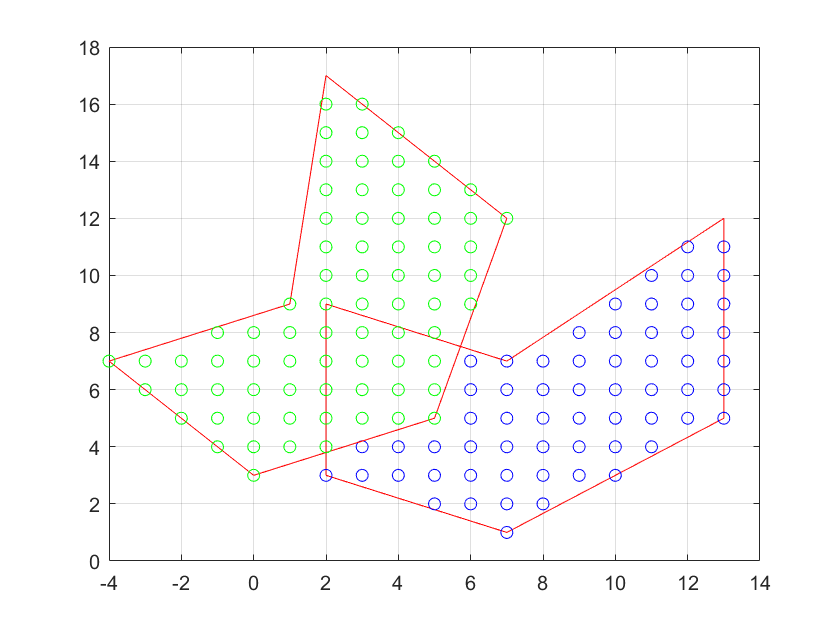

% 测试旋转脚本
% 初始x与y的坐标集合
x_origin = [2, 7, 13, 13, 7, 2];
y_origin = [3, 1, 5, 12, 7, 9];
% 用扫描线算法绘制初始多边形
scan_line(x_origin, y_origin, "bo")

% 设置绕的固定点
xc = 1;
yc = 1;
% 设置旋转角度
theta = pi/4;
% 根据矩阵运算得到新的x与y的坐标
[x, y] = rotate(xc, yc, x_origin, y_origin, theta, "matrix");
% 根据平移得到新的x与y的坐标
% [x, y] = rotate(xc, yc, x_origin, y_origin, theta, "move");

% 绘制新生成的多边形
scan_line(x, y, "go");